# MR Signal Equations

Pulse sequences create an MR signal that depends on the specific parameters used for that sequence.  For several important pulse sequences, we have equations that describe the size of the signal we expect, given the parameters.  This tutorial describes and plots some of the signals.

This tutorial goes through the sequences and the equations for major types of acquisitions.

As a reminder, here are the T1 and T2 parameters of gray and white matter

                **Tissue**  | **T1** (1.5T,3.0T,4T)   |     **T2** (1.5T,3.0T,4T) (sec)  | T2* (1.5T, 3T)

                ------------------------------------------------------------------------------------------------------

                White     0.64, 0.86, 1.04       |     0.080, 0.080, 0.050       |  0.067,

                Gray       0.88, 1.20, 1.40       |     0.080, 0.110, 0.050       |  0.048, 

                ------------------------------------------------------------------------------------------------------

            **Source**: Jezzard and Clare Chapter 3 in the Oxford fMRI Book.  The numbers differ   somewhat between different publications (e.g.,  "[NMR relaxation times in the human brain at 3.0 tesla](https://pubmed.ncbi.nlm.nih.gov/10232510/)")

Also:  T2* at 1.5T from [http://www.ajnr.org/content/29/5/950](http://www.ajnr.org/content/29/5/950) Table 1.  They have a T2 of 96 ms in GM and 110 in WM.

And:  T2 at 3T [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC5390949/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC5390949/) and [https://link.springer.com/article/10.1007%2Fs11682-016-9550-5](https://link.springer.com/article/10.1007%2Fs11682-016-9550-5) 

[https://link.springer.com/article/10.1007/s10334-016-0573-0](https://link.springer.com/article/10.1007/s10334-016-0573-0) 3T

## Spin Echo

Four parameters define the spin echo signal equations.  Two are pulse sequence choices:  TR (repetition time), TE (echo time) and two are material properties (T1 and T2).

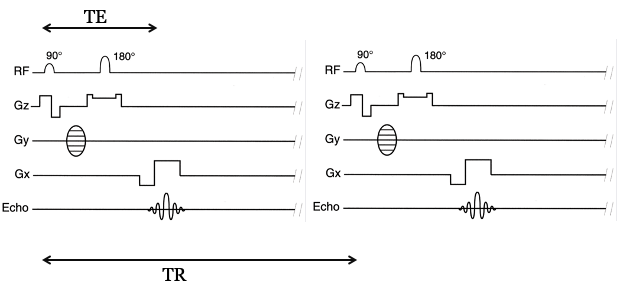

Here is the equation relating SE signal to these parameters:


$$\mathrm{signal}\left(\mathrm{SE}\right)=\left(1-\exp \left(-\frac{\mathrm{TR}}{\mathrm{T1}}\right)\right)\;\left(e\mathrm{xp}\left(-\frac{\mathrm{TE}}{\mathrm{T2}}\right)\right)$$


## Calculating the Spin Echo signal

TR = 2;   % sec
T1 = 1.1; % sec
TE = (0.02:0.02:0.40);  % 20 ms to 400 msec


## Gradient Echo

The Gradient Echo Sequence has this pulse diagram

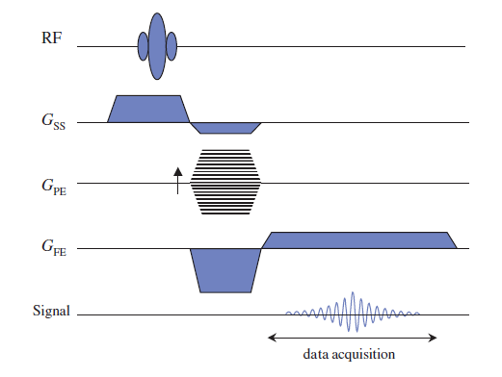

The key parameters for the sequence are the flip angle $$\alpha$$, TR, TE, T1 and T2*.  The formula is


$$Signal(GE) = M_0 {\frac{sin(\alpha) (1 - exp^{(-TR/T1)} )e^{(-TE/T2*)}}{1 - cos(\alpha)(1 - exp^{-(TR/T1)})}$$


## Calculating the GE signal

We can write the parameters and Matlab expression this way

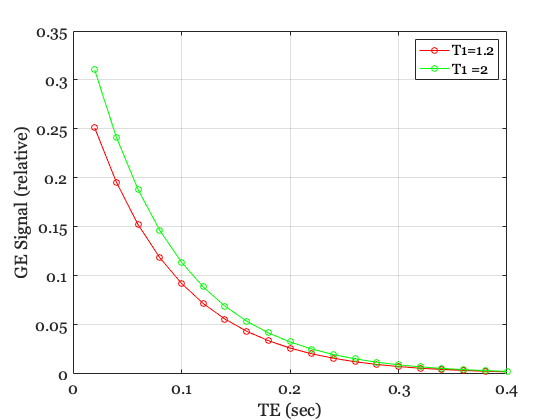

M0 = 1;      % To ignore, treating as relative
FA = 60;     % deg
TR = 1;      % sec
T1 = 1.2;    % sec
T2star = 0.08;  % sec

% Sweep out a set of measurement times for the graident echo
TE = (0.02:0.02:0.40);  % 20 ms to 400 msec

% sind is sine for degree inputs
% The Gradient Echo Signal Equation
sig = sind(FA)*(1 - exp(-TR/T1))*(exp(-TE/T2star)) / ...
    (1 - cos(FA)*1 - exp(-TR/T1));

figure; 
plot(TE,sig,'-o');
grid on;

hold on;
TR = 2;
sig = sind(FA)*(1 - exp(-TR/T1))*(exp(-TE/T2star)) / ...
    (1 - cos(FA)*1 - exp(-TR/T1));
plot(TE,sig,'-o');
legend({'T1=1.2','T1 =2'})
xlabel('TE (sec)'); ylabel('GE Signal (relative)');

## [Spoiled Gradient Echo Recalled (link)](https://mriquestions.com/spoiling---what-and-how.html)

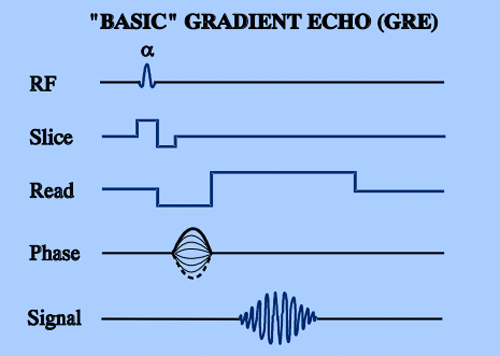 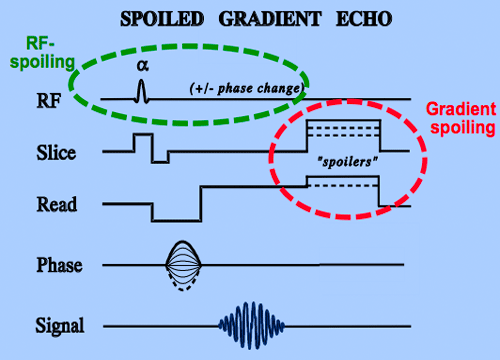

## Inversion Recovery